%% AUTHOR INFORMATION
% NAME: Ashwin Balagopal S
% EMAIL: ee17d200@smail.iitm.ac.in
% Code to analyse the output from ./Test_Write_Drivers

## Preface

    clear ;
    clc ;
    if( ~exist( 'globalVars', 'var' ) )
        globalVars=[];
    end
    eval( [ 'clearvars -except globalVars ' sprintf( '%s ', globalVars ) ] ) ;
    close all ;
    zeroes = @( x ) zeros( x ) ;

## Go to Global

% Global : D:\Xilinx\Vivado_2018_Projs\Srinidhi_Laptop\PCB_TEST_FPGA_ARM\Character_Files\new_C_code_UART_files\10_vecfile_auto_FA\7_vecfile_auto_FA
% cd( '../../../' ) ;
%     fileName = mfilename ; 
%     filePath = matlab.desktop.editor.getActiveFilename ;
%     b = find( filePath == '\', 1, 'last' ) ; 
%     fileName = filePath( ( b + 1 )  : ( end - 4 ) ) ;
%     b = find( fileName == '_', 1, 'last' ) ; 
%     sourceFileName = fileName( 1 : ( b - 1 ) ) ;
% driverCode_fileName         = sprintf( '/%s', sourceFileName ) ;
% filePath            = '.' ;
% fpgaReceivedFile_name       = [ filePath '/fpgaRcvdFiles' driverCode_fileName ] ;
% [    fpgaReceivedFile_decrypted ...
%             , adc_VPVN ...
%             , adc_AUX00 ...
%             ,    SA_SC_collect    ...
%             ,    ADC_SC_collect  ...
%             ,    AdderTree_SC_collect  ...
%             ,    SARTIMING_OUT_SC_collect  ...
%             ,    WRITE_2_SC_collect  ...
%             ,    WRITE_1_SC_collect  ...
%             ,    WRITE_0_SC_collect  ...
%             ,    IMC_RBL_SC_collect  ...
%             ,    IMC_VOut_SC_collect  ...
%             ,    WWL_SC_collect  ...
%             ,    FLOATADC_SC_collect  ...
%             ,    SARTIMING_IN_SC_collect  ...
%             ,    ControlPath_SC_collect  ...
%             ,    Reset_DFF_collect  ...
%             ,    SAR_Bin_Num ...
%            ,     read_SRAM_collect_Cell ] = decrypt_and_RSC( fpgaReceivedFile_name ) ;
% %% cd'ing back
%     cd( filePath ) ;
% %% saving data
%     c = clock ;
%     year    = c(1) ;
%     month   = c(2) ; 
%     day     = c(3) ;
%     hour    = c(4) ;
%     minute  = c(5) ;
%     seconds = floor(c(6)) ;
%save( [ sprintf( './analyzeResults/%s_%s_%d_%d_%d', fileName, date,hour,minute,seconds) ] ) ;
load('D:\Xilinx\Vivado_2018_Projs\IMC_CHIP_2023\PCB_v3\MATLAB_CONTROL\Control_Codes\Testing\012_CurrentMirrorCalibration\analyzeResults\postCalbTest_v3_analyse_11-Sep-2023_20_20_35.mat');

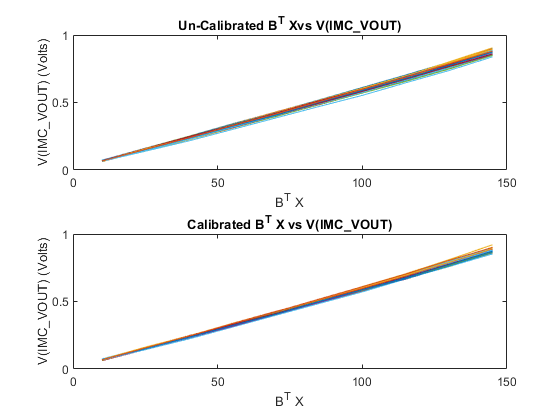


figure(1);
numOnesData_array=[10:15:150];
MAC_Xfers_calib=reshape(adc_VPVN,10,[]);
%load('D:\Xilinx\Vivado_2018_Projs\IMC_CHIP_2023\PCB_v1\MATLAB_CONTROL\Control_Codes\Testing\011_CurrentMirrorFunctionality\MAC_xfers_unCalib.mat');
load('D:\Xilinx\Vivado_2018_Projs\IMC_CHIP_2023\PCB_v3\MATLAB_CONTROL\Control_Codes\Testing\012_CurrentMirrorCalibration\withoutCalib_MAX_Xfers.mat');
MAC_xfers_unCalib=withoutCalib_MAX_Xfers;
subplot(2,1,1)
plot(numOnesData_array,MAC_xfers_unCalib);
title('Un-Calibrated B^T Xvs V(IMC\_VOUT)');
xlabel('B^T X');
ylabel('V(IMC\_VOUT) (Volts)');

load('D:\Xilinx\Vivado_2018_Projs\IMC_CHIP_2023\PCB_v3\MATLAB_CONTROL\Control_Codes\Testing\012_CurrentMirrorCalibration\withCalib_MAX_Xfers.mat');
MAC_xfers_Calib=withCalib_MAX_Xfers;
subplot(2,1,2)
plot(numOnesData_array,MAC_xfers_Calib);
title('Calibrated B^T X vs V(IMC\_VOUT)');
xlabel('B^T X');
ylabel('V(IMC\_VOUT) (Volts)');

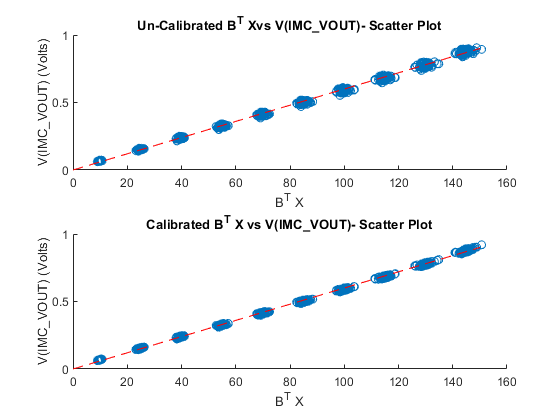



figure(2);
load('D:\Xilinx\Vivado_2018_Projs\IMC_CHIP_2023\PCB_v3\MATLAB_CONTROL\Control_Codes\Testing\028_SystemMAC_DryRuns\alphas_72.mat');
A=triu(ones(1024));alphaMACs=(A(:,[10:15:150]))'*alpha_DLStore;
load('D:\Xilinx\Vivado_2018_Projs\IMC_CHIP_2023\PCB_v3\MATLAB_CONTROL\Control_Codes\Testing\012_CurrentMirrorCalibration\withoutCalib_MAX_Xfers.mat');
MAC_xfers_unCalib=withoutCalib_MAX_Xfers;
subplot(2,1,1);
scatter(alphaMACs(:),MAC_xfers_unCalib(:));
hold on;plot( [0 150], [0 0.9], '--r' ) ;
title('Un-Calibrated B^T Xvs V(IMC\_VOUT)- Scatter Plot');
xlabel('B^T X');
ylabel('V(IMC\_VOUT) (Volts)');

load('D:\Xilinx\Vivado_2018_Projs\IMC_CHIP_2023\PCB_v3\MATLAB_CONTROL\Control_Codes\Testing\012_CurrentMirrorCalibration\withCalib_MAX_Xfers.mat');
MAC_xfers_Calib=withCalib_MAX_Xfers;
subplot(2,1,2);
scatter(alphaMACs(:),MAC_xfers_Calib(:));
hold on;plot( [0 150], [0 0.9], '--r' ) ;
title('Calibrated B^T X vs V(IMC\_VOUT)- Scatter Plot');
xlabel('B^T X');
ylabel('V(IMC\_VOUT) (Volts)');
hold off;